% пробую сгенерить си код

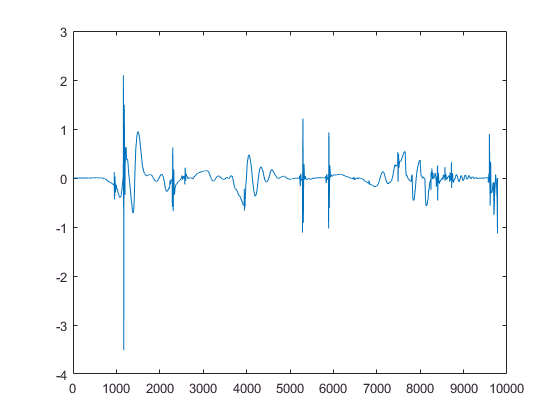

x=tYawAcc(:, 2);
plot(x)

nWht = 64

nWht = 64

n_section = 6

n_section = 6

nSectionPlus=7;
msp = zeros(1, 64);
load("kwhd.mat")
load("dSigm.mat")
kw = kwh64(:,4:51);


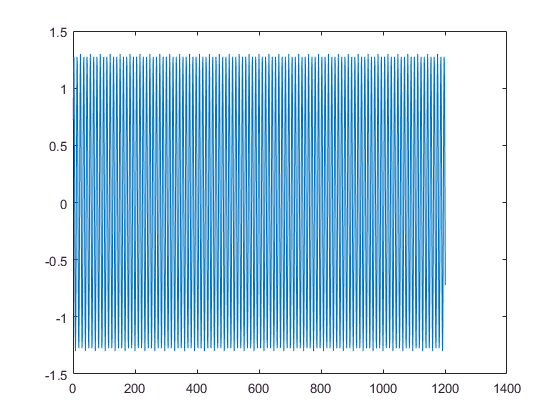

nnn = 1201;
y00 = 1:1201;
y01 =1.3* sin(6*2*pi/64*y00);
plot(y01)

x=y01;


yy00 = y01(1:64);
y = abs(fwht(yy00));
%plot(y)
mWhCalc=abs(yy00*kw);
ik0=1:2:length(mWhCalc);
ik1=1:2:length(mWhCalc);
m0=mWhCalc(ik0) + mWhCalc(ik1);
energy = sum(m0)

energy = 218.9919

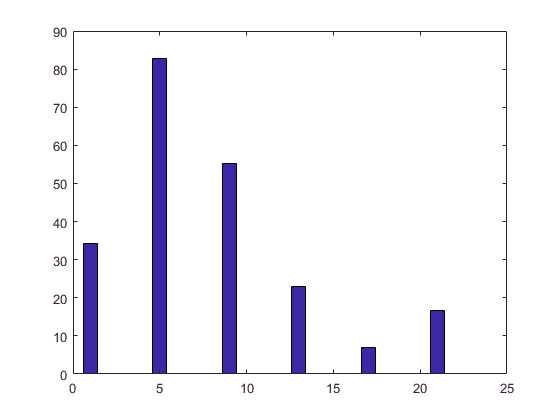

figure
bar(m0)

wh_deg = WhDebagSimul();
%x=tYawAcc(:, 2);
plot(x)

plot(x(1:nnn))

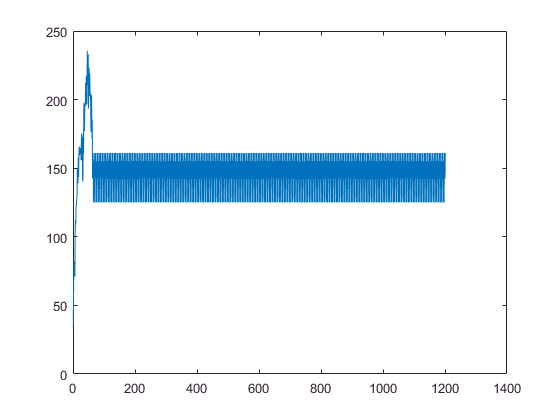

msp(:)=0;
v0=zeros(nnn, 24);
v1=zeros(nnn, 1);

%for ix=1:nnn    %length(x)
for ix=1: length(x)
    msp(1, 2:nWht) = msp(1, 1:nWht-1);
    msp(1,1) = x(ix);
    v1(ix, 1)=sum(abs(msp*kw));
    
end
plot(v1)

disp(" расчет закончен ")

 расчет закончен 


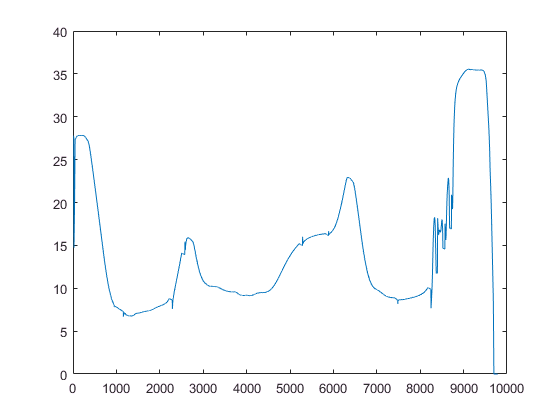

vBelt=tvBelt(:, 2);
plot(vBelt)

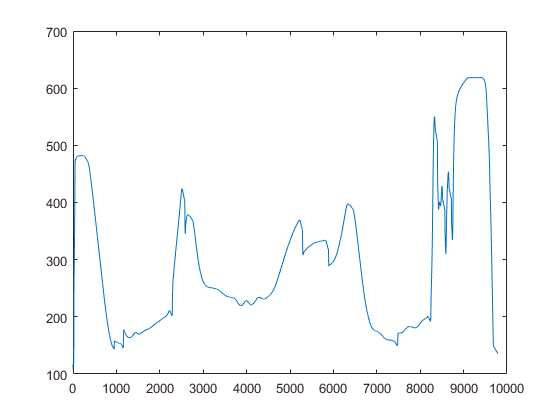

rotv=trotv(:, 2);
plot(rotv)

dSlipp = zeros(1, 50);
lSlipp = length(dSlipp)

lSlipp = 50


Rwheel=17*0.0254

Rwheel = 0.4318

Transfer = 3

Transfer = 3

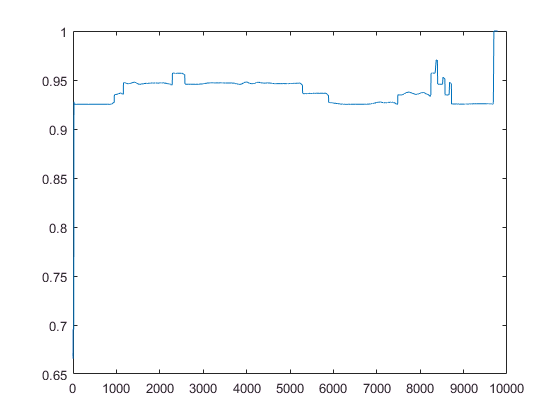

R =  Rwheel * Transfer;
            
slipp = 1 - (vBelt./rotv*R );            
plot(slipp)

dSlipp = zeros(1, 30);
lSlipp = length(dSlipp);
ind =1 

ind = 1

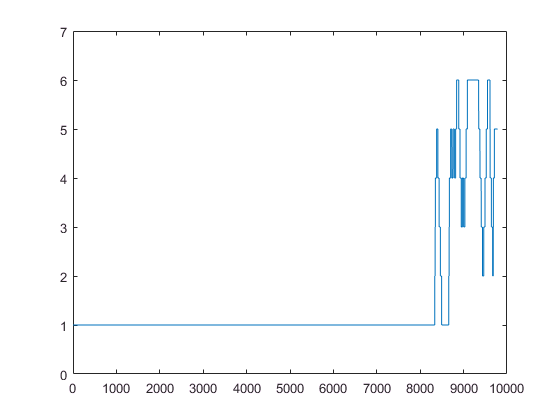

dSlipp(:)=0.0;
%vK = zeros(1,300);
vK = zeros(1, length(slipp));
for i=1: length(slipp)
    dSlipp( 2:lSlipp) = dSlipp(1:lSlipp-1);
    dSlipp(1) = slipp(i);
    
%    if mod(i, 500)==0 disp(i) end
    
    % I - Режим формирования массива dSlipp     
    if dSlipp(lSlipp)==0
        vK(i) = ind;    
        continue;
    end
    
    sr = sum(dSlipp)/length(dSlipp);
    sd3 = std(dSlipp)*4;
%    sd2 = std(dSlipp)*2;
    
% II - Режим ind == 1
    if ind==1
        if dSlipp(1)>(sr + sd3)   
            ind=min(ind+1, 6);
            vK(i) = ind;    
            continue;
        end            
        if dSlipp(1)<(sr - sd3)   
            ind=max(ind-1, 1);
            vK(i) = ind;    
            continue;
        end
        vK(i) = ind;            
        continue;
    end
    
% III - Режим ind > 1
    if (dSlipp(1)>(sr + sd3)) & (dSlipp(1)>dSlipp(2))
        ind=min(ind+1, 6);
%         xx=(dSlipp(1)-dSlipp(2))/dSlipp(2)*100;
%         sss = sprintf('i=%d; ind=%d; dSlipp(1)=%d; dSlipp(2)=%d; sr + sd3=%d; sr=%d; sd=%d; xx=%d', i, ind, dSlipp(1), dSlipp(2),sr + sd3, sr, sd3, xx);
%        disp(sss)

        vK(i) = ind;    
        continue;
    end
    if (dSlipp(1)<(sr - sd3)) & (dSlipp(1)<dSlipp(2))
        ind=max(ind-1, 1);
        vK(i) = ind;    
        continue;
    end
    dSlipp(1)=dSlipp(2);        
        
    vK(i) = ind;    
end
figure
plot(vK)
ylim([0 7])